clear all
close all

%data that was given by doc or prof
vr = 20; %rotating speed in rpm
fr = vr / 60; %shaft rotating frequency

%init
Date = ["2014-03-26" "2014-04-28"];
color_p = ['r', 'b', 'g'];
%f_meca = [{'vib1'} {'vib2'} {'vib3'} {'lss'} {'hss'}];
f_meca = [{'lss'}];
nFields = length(f_meca);
figs = figure('Name', 'All spectra');

for p = 1:length(Date) %loop on files (dates)
    date = Date(p);
    %dataDir = 'Z:\4A\WindTurbineMonitoring\data\'; %uigetdir; %gets directory
    dataDir = 'D:\3a_sicom_eeh\Project_wind_turbine\data\';
    allFiles = dir(fullfile(dataDir, date + "*"));
    old_data = load(strcat(dataDir, allFiles(1).name));
    %merge fields to create one large data srtuture
    for i = 2:length(allFiles)
        data = load(strcat(dataDir, allFiles(i).name));
        f = fieldnames(old_data);
        for j = 1:length(f)
            data.(f{j}) = old_data.(f{j});
        end
        old_data = data;
    end

    % First analyse mecanical data: vib123 and lss and hss
    data_meca = [];
    for j = 1:nFields
        data_meca.(f_meca{j}) = data.(f_meca{j});
    end

    figt = figure('Name', 'Figure for date ' + Date(p))
    
    for k = 1:nFields %loop on variables (fields) to plot
        figure(figt)
        subplot(1,nFields,k)
        cur_data = data_meca.(f_meca{k});
        cur_raw = cur_data.rawData;
        fs = cur_data.fs;
        ts = 1/fs;
        t0 = cur_data.timeStamp;
        nsamples = length(cur_raw);

        time_axis = linspace(t0, t0 + ts * nsamples, nsamples);
        plot(time_axis, cur_raw)
        title(cur_data.sensorName + " / " + cur_data.unit)
        xlabel("Time / s")
        ylabel(cur_data.unit)

        figure(figs)
        subplot(1,nFields,k); hold on;
        T = time_axis(end)-time_axis(1);
        freq_axis = linspace(0, 1/T * fs/2, nsamples/2);
        spectr = abs(fft(cur_raw)); %matlab functions pour spectre direct + périodogramme moyenné (pwelch) plus adapté car bruité
        plot(freq_axis(2:end), spectr(2:(nsamples/2)), color_p(p))
        title("Module spectrum of " + cur_data.sensorName)
        xlabel("Frequency / Hz")
        grid on;
    end

end

figt =   Figure (8: Figure for date 2014-03-26) with properties:

      Number: 8
        Name: 'Figure for date 2014-03-26'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


figt =   Figure (9: Figure for date 2014-04-28) with properties:

      Number: 9
        Name: 'Figure for date 2014-04-28'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


On a un signal x(t) aléatoire et stationnaire. On peut en calculer la DSP mais celle-ci ne convergera pas si l'on prend le signal en entier $S_{\mathrm{xx}} \left(f\right)=E\left\lbrack {\mathrm{lim}}_{T->\infty } \frac{{|X_T \left(f\right)|}^2 }{T}\right\rbrack =\mathrm{DSP}$

On découpe alors le signal en plusieurs morceaux afin de pouvoir calculer cette espérance. Il faut alors trouver le juste milieu entre résolution fréquentielle et nombre de données. Si l'on découpe notre signal en L morceaux, Chaque morceau composé de N échantillons. 


$$\begin{array}{l}
T_{\mathrm{total}} =L\ldotp T=L\ldotp N\ldotp T_e \\
\Delta f=\frac{1}{N\ldotp T_e }=\frac{f_e }{N}
\end{array}$$


Dans notre cas deux fréquences doivent être identifiées : f_o et f_i. Il nous faut donc une résolution R suffisante.$\Delta f=\frac{f_e }{N}=\frac{R}{10}$ avec $R=\frac{f_i }{f_o }$.

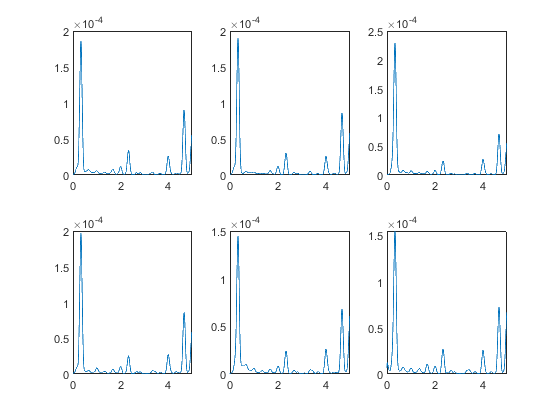

close all; 
clear all;
%% Data
Date = ["2014-03-26" "2014-04-01" "2014-04-03" "2014-04-09" "2014-04-24" "2014-04-28"];
color_p = ['r', 'b', 'g', 'k', 'm', 'c'];
f_meca = [{'lss'}];
nFields = length(f_meca);
dataDir = 'D:\3a_sicom_eeh\Project_wind_turbine\data\';

%% Values
fo = 7.65/3; %Prendre plutot val moyenne frequence
fi = 10.35/3; %Prendre plutot val moyenne frequence
R = fi-fo;
df = R/10;

for p = 1:length(Date)
    date = Date(p);
    allFiles = dir(fullfile(dataDir, date + "*"));
    old_data = load(strcat(dataDir, allFiles(1).name));
    %merge fields to create one large data srtuture
    for i = 2:length(allFiles)
        data = load(strcat(dataDir, allFiles(i).name));
        f = fieldnames(old_data);
        for j = 1:length(f)
            data.(f{j}) = old_data.(f{j});
        end
        old_data = data;
    end
    data_meca = [];
    for j = 1:nFields
        data_meca.(f_meca{j}) = data.(f_meca{j});
    end
    cur_data = data_meca.(f_meca{1});
    cur_raw = cur_data.rawData;
    fs = cur_data.fs;
    nsamples = length(cur_raw);
    
    %% Values
    fe = fs;
    N = round(fe/df);
    %Nb_seg = int(nsamples/N);
    
    %%Variable a def
    Overlap = round(3*N/4);
    
    
    cur_raw = cur_raw-mean(cur_raw);
    [res,f]= pwelch(cur_raw,N,Overlap,10*N,fe);
    figure(1);
    subplot(2,3,p)
    plot(f,res);
    xlim([0 5]);
end